%% Setup a cone mosaic
imageSize = [128, 128, 3];
display = displayCreate('CRT12BitDisplay');
prior   = load('sparsePrior.mat');

fovDegs = 0.20;
pupilSize = 3.0;
retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', fovDegs, 'display', display, 'pupilSize', pupilSize, ...
    'integrationTime', 1.0);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 30.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.249064, Tolerange: 0.001000
Number of Delaunay triangulations: 8
[PASS:  1/ 3]. Adjusting cones between 30.00 44.96 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment:

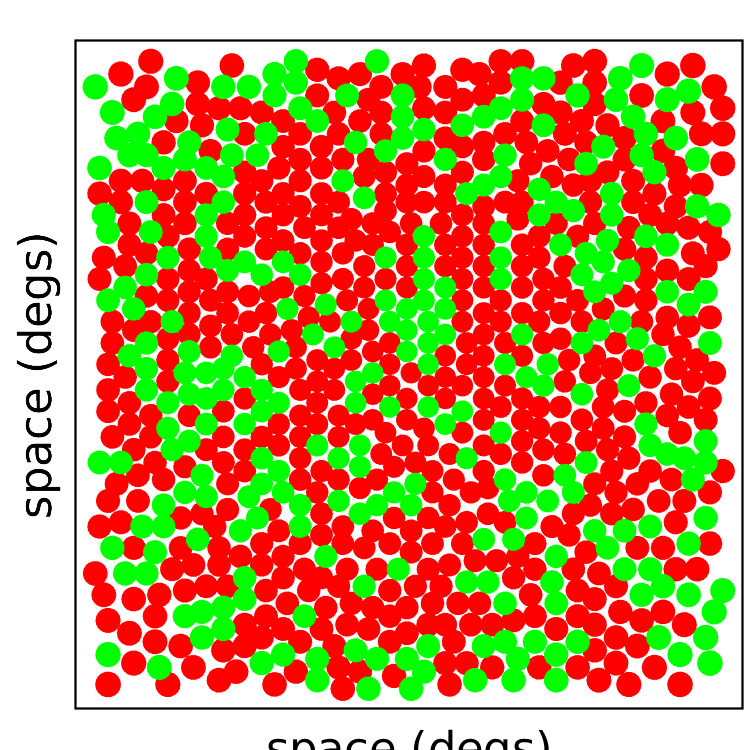


retina.resetSCone();
retina.reassignSCone(0.1);
retina.visualizeMosaic();

%% Regular optics
retina.PSF = oiCreate('human', pupilSize);
render = retina.forwardRender(imageSize);
render = double(render);

%% Compute cone excitation with gratings
spatialFreq = 16;

rmsContrast = 1.0;
chromaDir = [1.0, 1.0, 1.0]';
chromaDir = chromaDir / norm(chromaDir) * rmsContrast;

gratingScene = ...
    createGratingScene(chromaDir, spatialFreq, 'fovDegs', fovDegs, 'pixelsNum', 1024);

crst = 1.0;
[theSceneSequence, ~] = gratingScene.compute(crst);

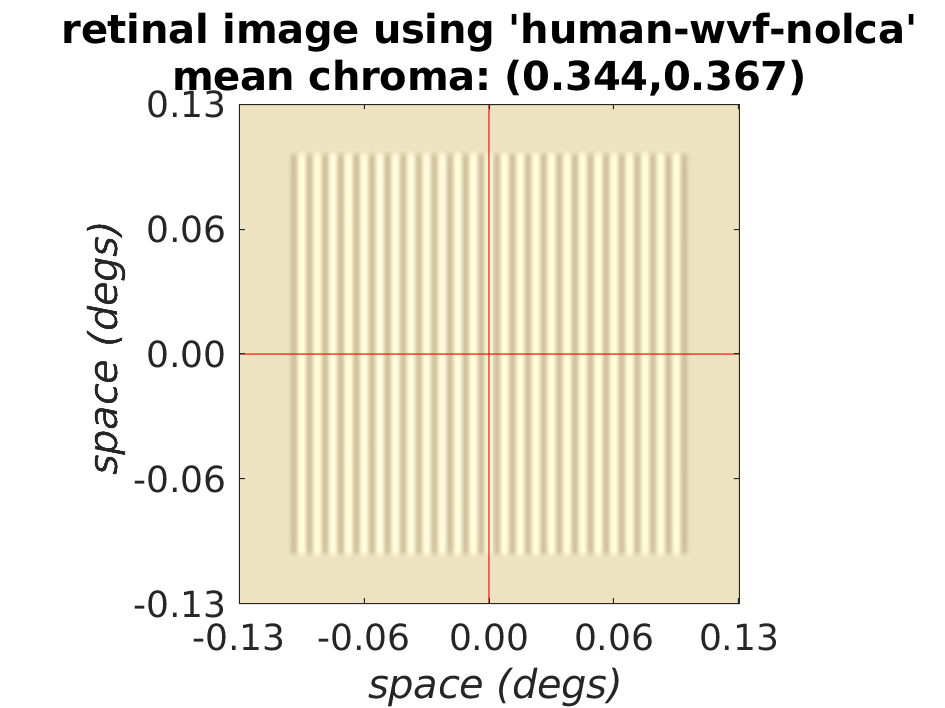

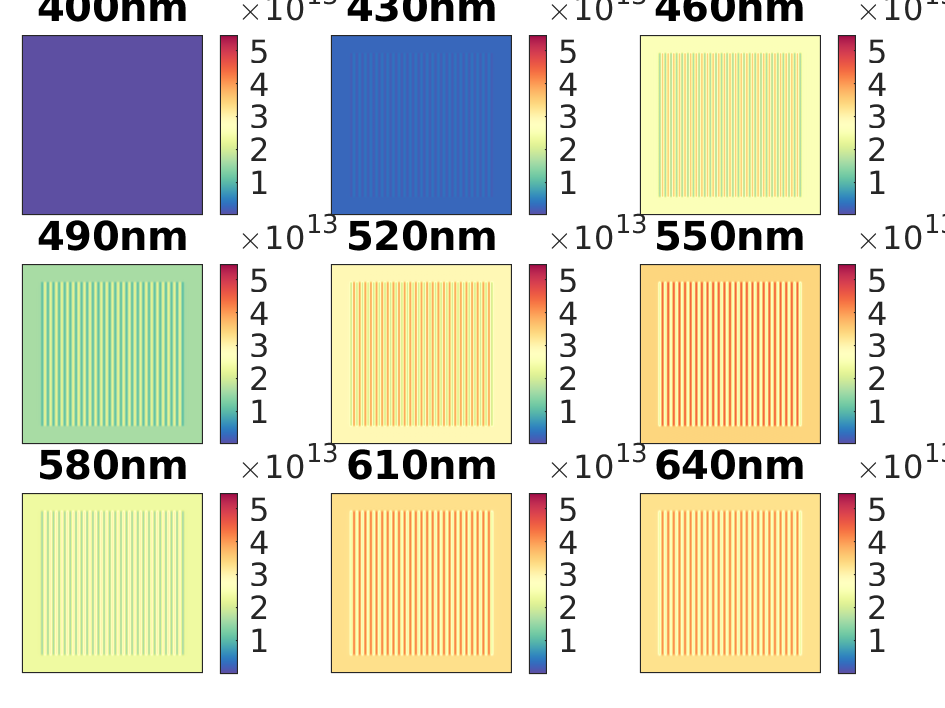

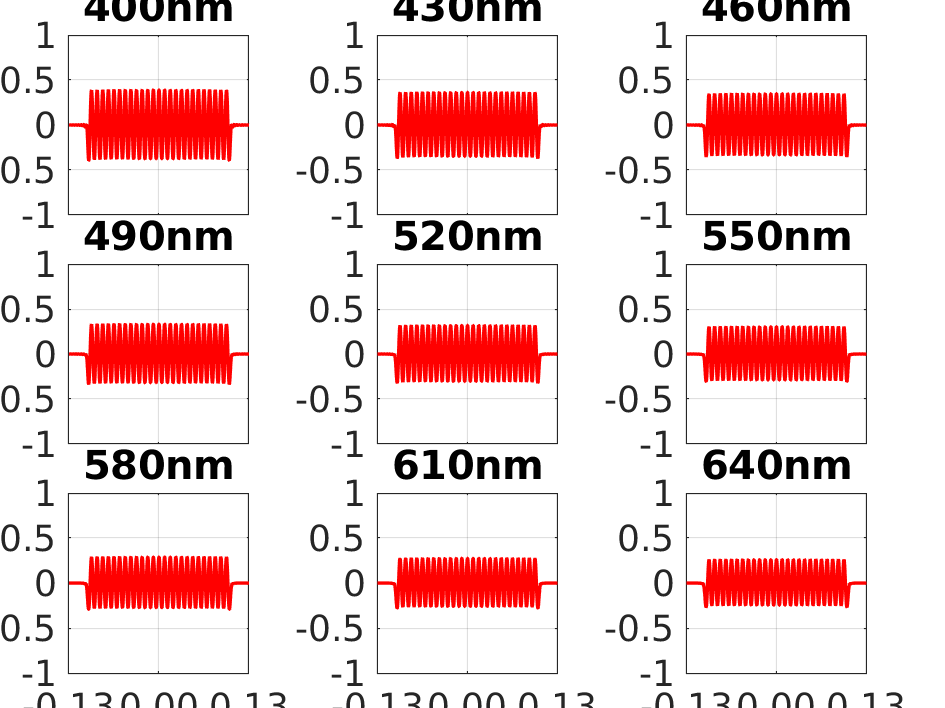

% Compute response from scene
[~, allCone] = retina.computeWithScene(theSceneSequence{:});
visualizeOpticalImage(retina.LastOI, 'displayRadianceMaps', true, ...
                'displayRetinalContrastProfiles', true);

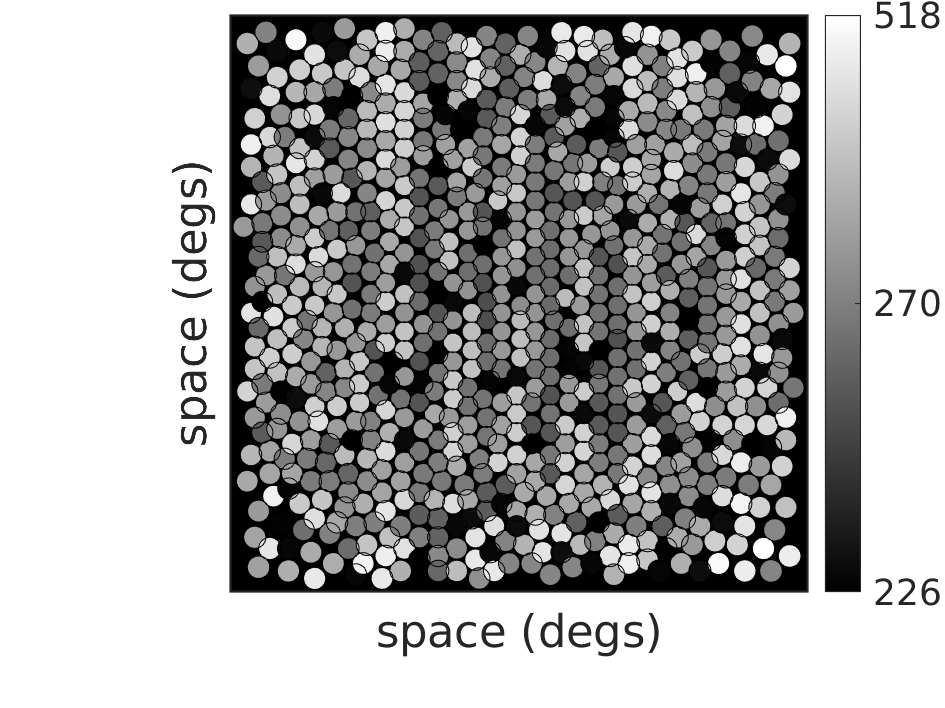

% Visualize pattern of cone excitation
retina.visualizeExcitation();

%% Turn off optics
% Use a large pupil size to reduce the effect of diffraction
diffPupil = 10.0;
retina.PSF = ConeResponse.psfDiffLmt(diffPupil);

renderDiflmt = retina.forwardRender(imageSize);
renderDiflmt = double(renderDiflmt);

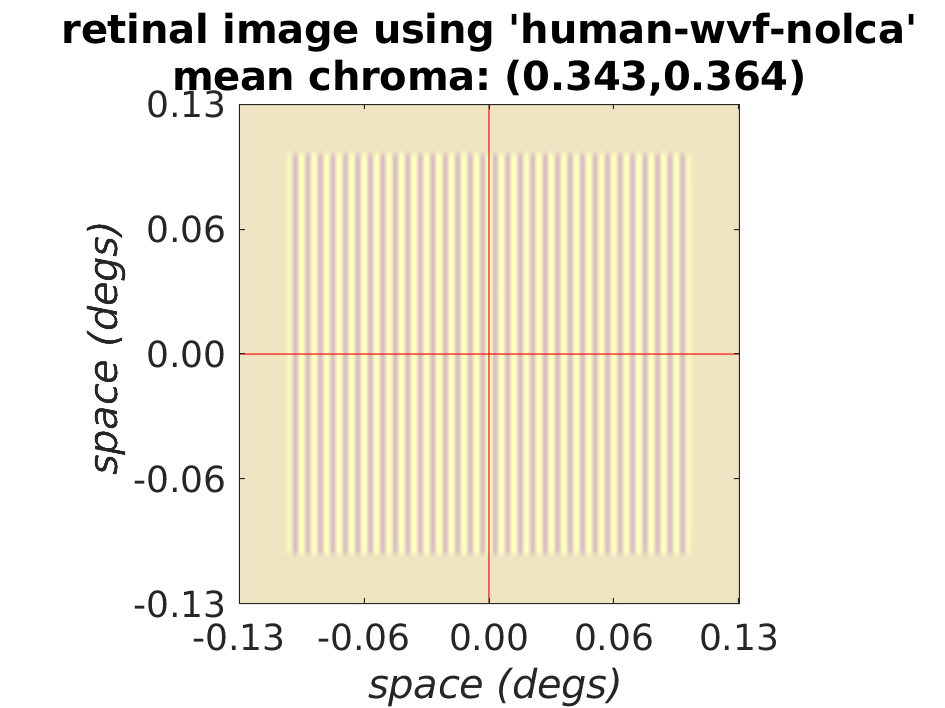

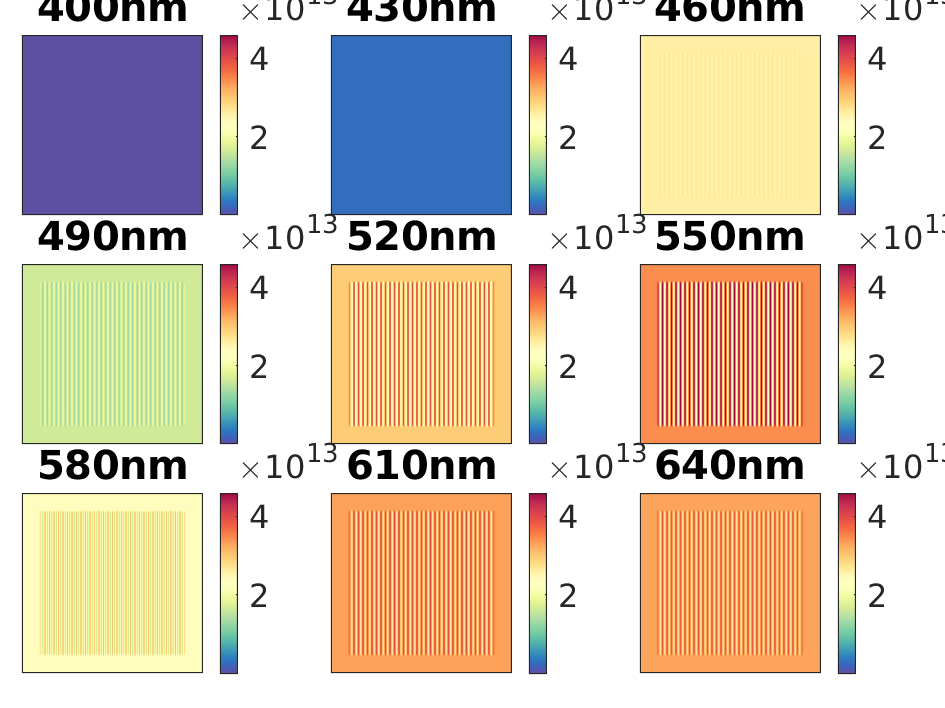

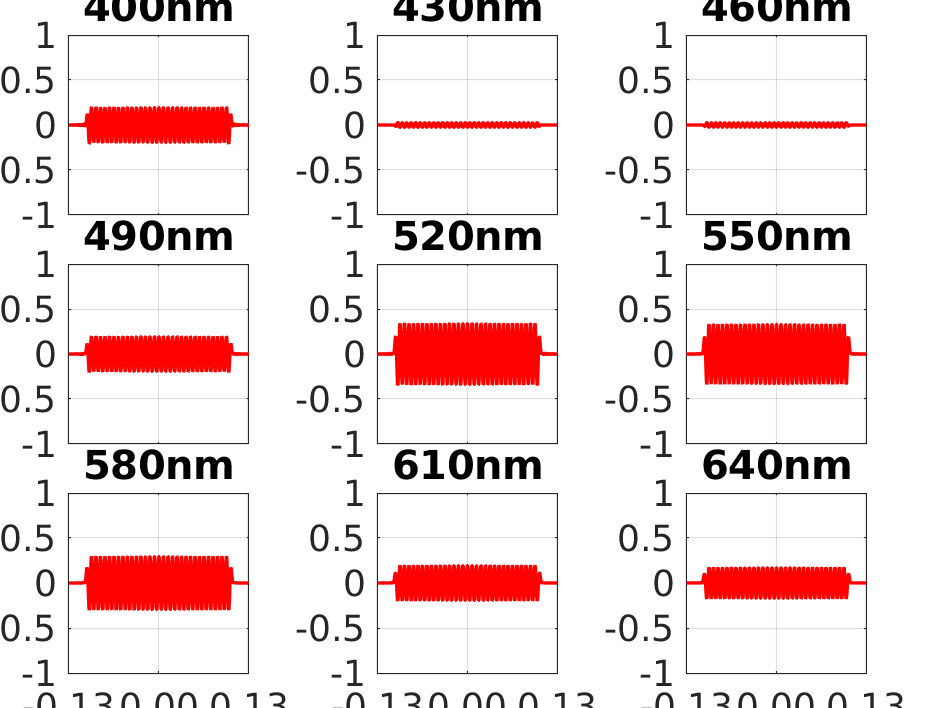

%% Compute cone excitation with gratings
spatialFreq = 16;

rmsContrast = 1.0;
chromaDir = [1.0, 1.0, 1.0]';
chromaDir = chromaDir / norm(chromaDir) * rmsContrast;

gratingScene = ...
    createGratingScene(chromaDir, spatialFreq, 'fovDegs', fovDegs, 'pixelsNum', 1024);

crst = 1.0;
[theSceneSequence, temporalSupport] = gratingScene.compute(crst);

% Compute response from scene
[~, allCone] = retina.computeWithScene(theSceneSequence{:});
visualizeOpticalImage(retina.LastOI, 'displayRadianceMaps', true, ...
                'displayRetinalContrastProfiles', true);

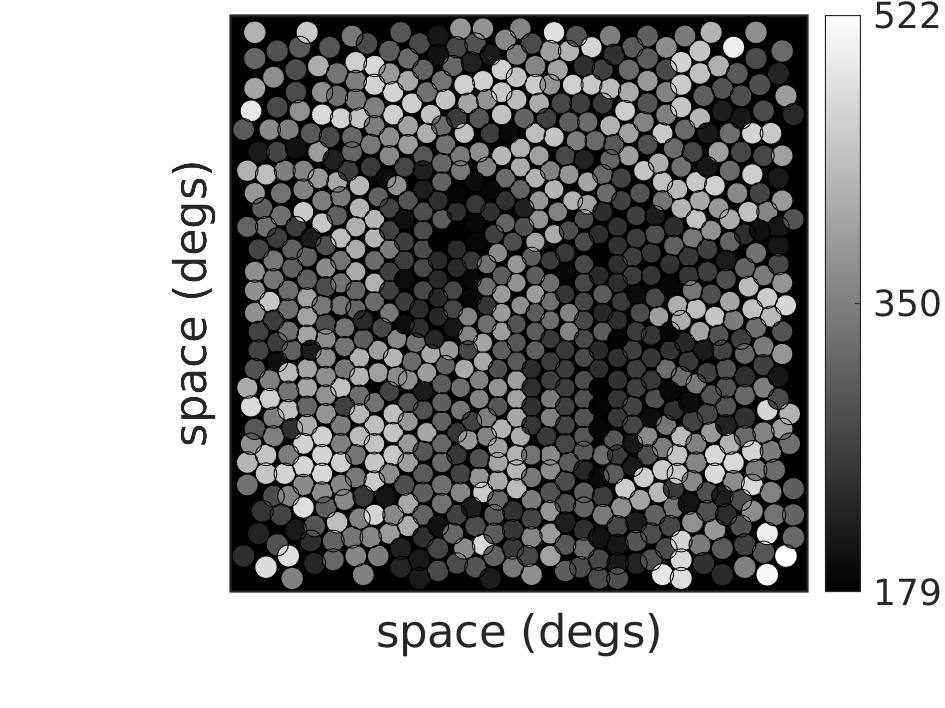

% Visualize pattern of cone excitation
retina.visualizeExcitation();